clc; clear all; close all; 

## Data Summary and Visualisation

### Working Directory

% Set working directory to the current directory 
addpath('src');
addpath("data/raw/")
setwdtocurrent()

### Import Data

Loading Sheet 1:

No0x2E2WT


Loading Sheet 2:

No0x2E3


Loading Sheet 3:

No0x2E14WT


Loading Sheet 4:

No0x2E39WT


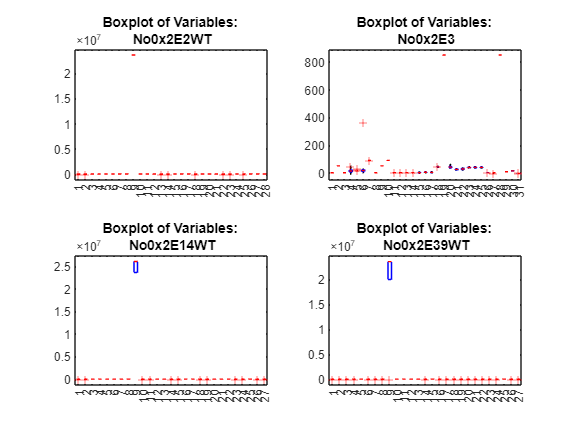

%Suppress warnings
warning('off');

% Define the Excel file name
excelFileName = 'data.xlsx';

% Get the sheet names from the Excel file
[~, sheetNames] = xlsfinfo(excelFileName);

% Loop through each sheet, read it into a table and get summary statistics
for i = 1:length(sheetNames)
    fprintf("Loading Sheet %d:", i)
    sheetName = sheetNames{i};
    % Generate a valid variable name in MATLAB
    tableName = genvarname(sheetName); 
    tableData = readtable(excelFileName, 'Sheet', sheetName, 'ReadVariableNames', true);
    % Save the table with the sheet name as the table name
    assignin('base', tableName, tableData);
    %Display the table name
    disp(tableName)

    % Save the summary stats in an excel file
    currentDir = pwd;
    mainFolder = 'data';
    subFolder = 'processed';
    destinationFolder = fullfile(currentDir, mainFolder, subFolder);

    % Create the folder if it does not exist
    if ~exist(fullfile(currentDir, destinationFolder), 'dir')
        mkdir(fullfile(destinationFolder));
    end

    % Define the output file name
    outputFileName = fullfile(destinationFolder, 'summary.xls');
    
    % Write the table to Excel
    writetable(summarystats(eval(tableName)), outputFileName, 'Sheet', i);

    
    % Visualize the data in the table using boxplots
    folderName = 'images';

    % Create a folder named "images" if it does not exist
    if ~exist(fullfile(currentDir, folderName), 'dir')
        mkdir(fullfile(folderName));
    end
    subplot(2, 2, i)
    boxplot(table2array(eval(tableName)))
    title([sprintf('Boxplot of Variables: \n'), tableName])

    if i==length(sheetNames)
        saveas(gcf, fullfile('images', 'unscaledBoxplot.png'));
        % close(gcf); 
    end
end

## Data Pretreatment

### Discard the dataset for `WT3`

clear No0x2E3;

### Drop one of the columns in the dataset for `WT2`

No0x2E2WT = removevars(No0x2E2WT, "x28");

### Drop the observation with the missing value

No0x2E14WT = rmmissing(No0x2E14WT);

### Data centering and scaling

model(1).No0x2E2WT

model(1).No0x2E14WT

model(1).No0x2E39WT

% Define the turbine numbers 
turbineNumbers = [2, 14, 39];

% Create a loop to process each turbine
for i = 1:length(turbineNumbers)
    turbineNumber = turbineNumbers(i);
    
    % Access the corresponding windTurbine table
    windTurbine = evalin('base', sprintf('No0x2E%dWT', turbineNumber));
    
    % Compute z-scores for the current turbine 
    fprintf(['model(1).' 'No0x2E' num2str(turbineNumber) 'WT'])
    model(1).(['No0x2E' num2str(turbineNumber) 'WT']) = zscore(table2array(windTurbine));
    
    % Set variable names for the models
    if i == 1
        model(1).varNames = No0x2E2WT.Properties.VariableNames;
    end
    
    % Create a boxplot for the current turbine
    figure;
    boxplot(model(1).(['No0x2E' num2str(turbineNumber) 'WT']));
    title([sprintf('Boxplot of Scaled Variables: \n'), num2str(turbineNumber) 'WT'])

    saveas(gcf, fullfile('images', ['No0x2E' num2str(turbineNumber) 'Boxplot.png']));
    % close(gcf);
end

Functions

function summaryOutput = summarystats(data)
    dim = size(data);
    noOfVar = dim(2);
    summaryOutput = array2table(zeros(noOfVar, 5));
    summaryOutput.Properties.VariableNames = {'Mean','Std dev.', 'Max','Min', 'Median'};
    rowNames = data.Properties.VariableNames;
    summaryOutput.Properties.RowNames = rowNames;
    
    for i=1:noOfVar
        variable = data{:,i};
        summaryOutput{i,1} = mean(variable);
        summaryOutput{i,2} = std(variable);
        summaryOutput{i,3} = max(variable);
        summaryOutput{i,4} = min(variable);
        summaryOutput{i,5} = median(variable);

    end
end